# Wind Turbine Study

For this exercise we are using data from a Wind Turbine in Turkey. The data is from 2018. More information on [https://www.kaggle.com/datasets/berkerisen/wind-turbine-scada-dataset](https://www.kaggle.com/datasets/berkerisen/wind-turbine-scada-dataset)

The objective is to study a day and see if we can find a function that describes the power output vs the windspeed relation and then validate it for the rest of the days. We also have data from the theoretical power output we should have, so we can also use that to see how efficient the turbine is. 

## Loading CSV from Turbine

Since the data was given in a CSV file, we have to do some processing to transform it to a more manageable object.

We first read the data from the csv and then we store the windspeed and power generated for each day.

T1 = readtable("T1.csv", 'Delimiter', ',', 'Format', '%{dd MM yyyy HH:mm}D %f %f %f %f');

% T1.Date = dateshift(T1.Date_Time, 'start', 'day');  % Create a new column for day
% uniqueDays = unique(T1.Date);  % Find all unique days
% dayDataStruct = struct();
% 
% for i = 1:length(uniqueDays)
%     % Extract data for the current day
%     currentDayData = T1(T1.Date == uniqueDays(i), :);
% 
%     % Store power and windspeed for this day in a structure
%     dayName = ['Day_', datestr(uniqueDays(i), 'yyyymmdd')];  % Unique name for the day
%     dayDataStruct.(dayName).power = currentDayData.LVActivePower_kW_;
%     dayDataStruct.(dayName).windspeed = currentDayData.WindSpeed_m_s_;
% end

## Save data to mat file

We can now save this to a matlab structure.

%save('DailyData.mat', '-struct', 'dayDataStruct');

## Load .mat file

Now we can load the structure and work with it.

load("DailyData.mat");

## Show data of one day

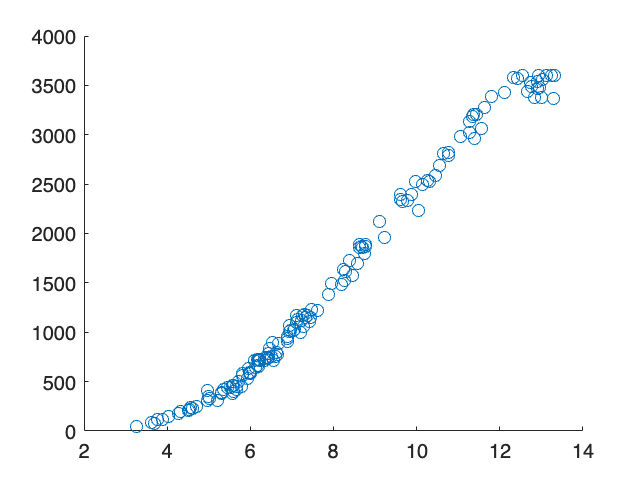

scatter(Day_20180101.windspeed,Day_20180101.power);

windspeed = Day_20180101.windspeed;
power = Day_20180101.power;

## Curve Fitting App

We used the curve fitting app to analyze the data and find the best fit we could for a single then, to then see how well it matches data from other days. The results are below.

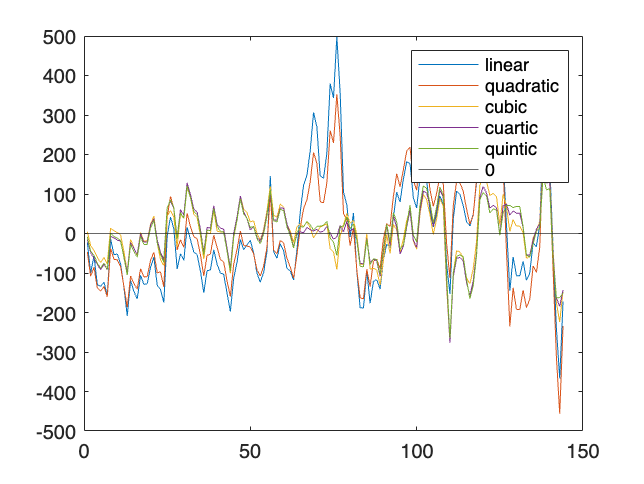

load fitOutput.mat;
figure('Name', 'Figure 1');
res = linearFit.residuals;
plot(res)
hold on
resq = quadraticFit.residuals;
resc = cubicFit.residuals;
rescuar= cuarticFit.residuals;
resqu= quinticFit.residuals;
plot(resq)
plot(resc)
plot(rescuar)
plot(resqu)
yline(0)
hold off
legend(["linear","quadratic","cubic","cuartic","quintic","0"])

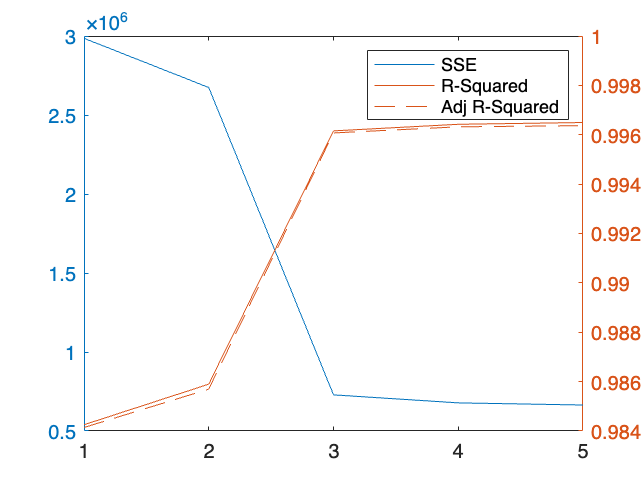


load goodnessOutput.mat;
goodness = [goodness1 goodness2 goodness3 goodness4 goodness5];
goodness = struct2table(goodness);
figure('Name', 'Figure 2');
yyaxis left
plot(goodness,"sse")
yyaxis right
plot(goodness,"rsquare")
hold on
yyaxis right
plot(goodness,"adjrsquare")
legend(["SSE","R-Squared","Adj R-Squared"])
hold off

From the residual plot we can see that the best options are either the cubic or cuartic fit.

From the goodness plot we can see that a polynomial of 3rd degree or higher is better but as we increase it, we get to a point where we can overfit. In this case, we are going to select the cuartic model since it has the best goodness values and does not overfit. 

## Model

Now that we have selected the quartic model, we can use it to compare it against the other days.

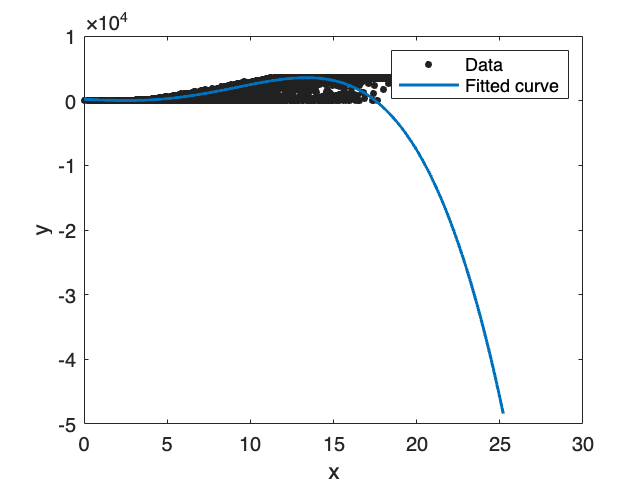

load cuarticModel.mat;
plot(cuarticModel,T1.WindSpeed_m_s_,T1.LVActivePower_kW_)

From the plot we can observe that the model is pretty good at predicting the power output for a certain speed, however, as the data used was only for one day, it did not contain some higher speeds. This, together with the fact that the model is polynomial, makes it bad at predicting beyong 20 m/s since it drops and this is not real, it should reach a maximum value. We will try to use another model to see if it predicts it better. Using the curve fitting app, we were able to create a sigmoidal model. This seems to be very good and predicts in a logical way.

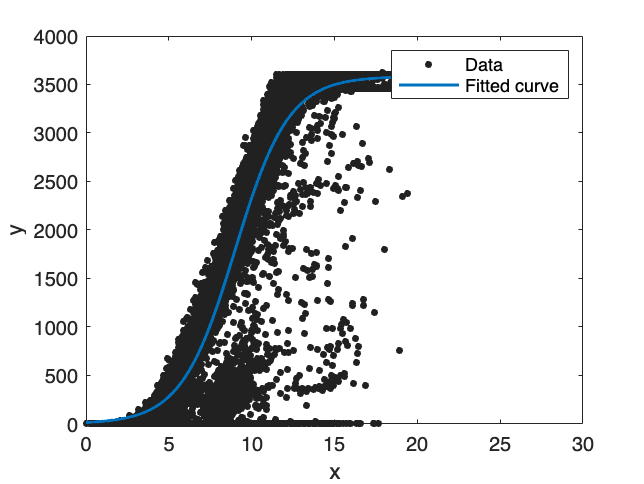

load sigmoidalModel.mat;
plot(sigmoidalModel,T1.WindSpeed_m_s_,T1.LVActivePower_kW_)

As we can see, this has a much better prediction. Finally, we want to compare if our model approaches the theoretical values of power we should get:

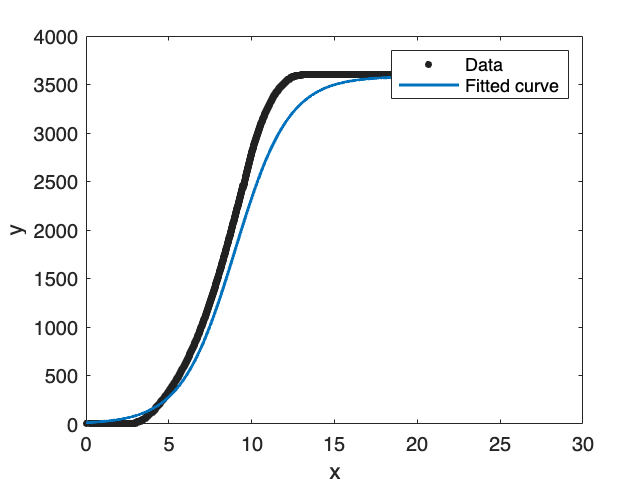

plot(sigmoidalModel,T1.WindSpeed_m_s_,T1.Theoretical_Power_Curve_KWh_)

As we can see from the theoretical values of the wind turbine, our curve approaches it pretty well. Specially at the beginning and end of the curve. Obviously there are many other things that can impact the curve but for this study, it was pretty interesting to see. 